# 04 Trust-Region Methods 

We are still solving the unconstraied optimization problem


$$\min_{x\in\mathbb{R}^n}{f(x)}$$


In ***trust region*** methods, we construct a *model function *$m_k$ at every iteration. The model function $m_k$ behavior near the current point $x_k$ is similar to that of the actual objective function $f$ .

We find a direction $p$ by solving the subproblem 


$$\min_{p}{m_k(x_k+p)}, \quad \|p\|_2\leq \Delta$$


where the scalar $\Delta > 0$ is called the trust-region radius.

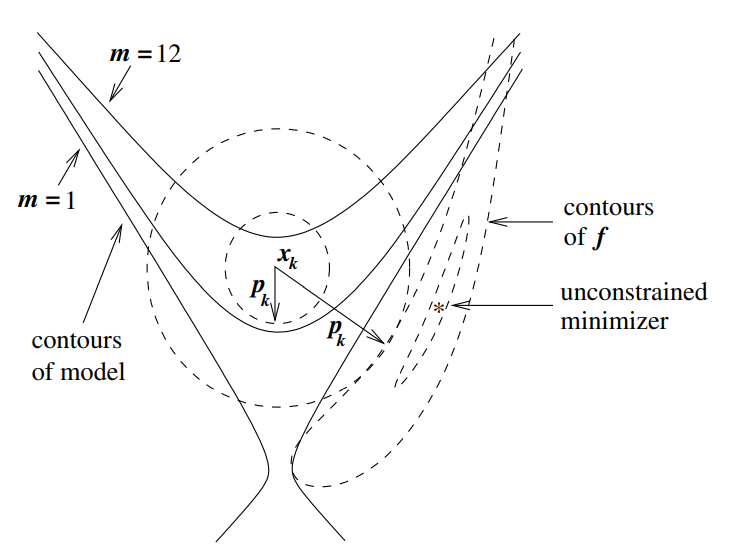

#### OUTLINE OF THE TRUST-REGION APPROACH

**Trust region methods** constitute a second fundamental class of algorithms. 

- In iteration $k$, replace $f(x)$ by a locally valid quadratic model function $m_k(x)$ 

- Choose a neighbourhood $R_k$ of the current iterate $x_k$ in which $m_k(x)$ can be trusted to approximate $f$ well (we do not care about how well $m_k$ approximates $f$ outside $R_k$).

- The next iterate $x_{k+1}$ is found by approximately minimizing the model function over the trust region, $x_{k+1} \approx   \text{arg}\min_{x\in R_k} m_k(x)$.

In this chapter, we will consider the quaratic model


$$m_k(p)= f_k+g_k^Tp_k + \frac{1}{2}p^TB_kp$$


and we solve the subproblem

 
$$\min_{p}{m_k(p)}, \quad \text{subject to }  \quad \|p\|_2\leq \Delta_k$$


**Remarks**:

- The linear part of $m_k(p)$ coincides with the first order Taylor approximation of $f(x)$.

- $m_k(p)$ will closely match the second order Taylor approximation of $f(x)$ when $B_k \approx  \nabla^2f(x_k).$

- To make the method work, we will thus have to worry about how to update $B_k$ cheaply.

- But note that the quasi-Newton Hessian approximations discussed in Chapter 3 are perfect for this job!.

**Accepting and Rejecting Updates**

- One of the key ingredients in a trust-region algorithm is the strategy for choosing the trust-region radius $\Delta_k$ at each iteration. Consider the ratio


$$\rho _k = \frac{f (x_k ) - f (x_k + p_k )}{ m_k (0) - m_k (p_k )}$$


-         Numerator $f(x_k)-f(x_k+p_k)$ is the actual reduction

-         Denominator $m_k(0)-m_k(p_k)$ is the predicted reduction 

-         If $\rho _k$ is close to 1, $m_k$ is a good model. In this case, if $||p_k||=∆_k$, increase $∆_k$. 

-         If $\rho _k$ is close to 0 or negative, shrink the range of the trust region $∆_k$.

Now,

- Let $p^*$ be the approximate minimizer of the trust region subproblem $m_k$. 

- In principle, this is the point we would like to use to have our next iterate $x_{k+1}$. $(x_{k+1}=x_k+p^*)$ 

- However, $p^*$ is computed on the basis of the model function $m_k$, and it could happen that moving to in the direction $p^*$ leads to an increase rather than decrease in of the true objective function $f.$

So,

- Trust-region methods therefore accept $p^*$ only if the decrease achieved in $f$ is at least a fixed proportion of the decrease ”predicted” by $m_k$, 


$$x_{k+1} = x_k+\left\{ \begin{array}{ll} p^* & \text{if }  \rho_k > \eta , \\ 0 &\text{otherwise}\end{array}\right.$$


            where η = 1/4 is fixed.

- Note that rejecting the update does not imply that the algorithm will stall, because we can still shrink the trust region so that the new $p^*$ is different than the old $p^*.$

**Updating the Trust Region **$R_k$: 

- The easiest way to define a trust region $R_k$ is to choose the closed ball of radius $∆_k$ around $x_k$ in some norm $\|\cdot\|$, 

                            
$$R_k = \left\{p \in  \mathbb{R}^n : \|p\|_2 \le  ∆_k \right\}.$$
 

- For simplicity, we will assume that $\|\cdot\|$ is the Euclidean norm. 

- $∆_k$ is called the trust region radius. 

- In order to define a new trust region $R_{k+1}$ around $x_{k+1}$, it suffices to fix a rule on how to select $∆_{k+1}.$ The following rule is a popular choice: 


$$\Delta_{k+1} = \left\{ \begin{array}{ll}     \frac{\Delta_k}{4} & \text{ if } \rho_k< \frac{1}{4} \\ \min\left(2\Delta_k,\Delta_{\max}\right) & \text{if } \rho_k>\frac{3}{4}\\ \Delta_k & \text{otherwise}\end{array}\right.$$


**Remarks:**

- $\hat{\Delta}=\Delta_{\max}$ (in what follows)

- $∆_k$ never exceeds $∆_{\max}.$

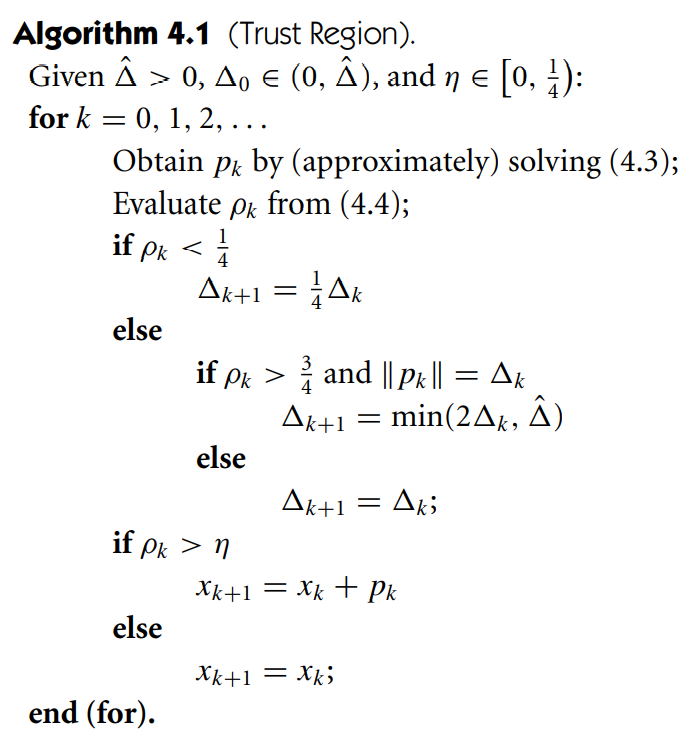 

#### Optimality conditions 

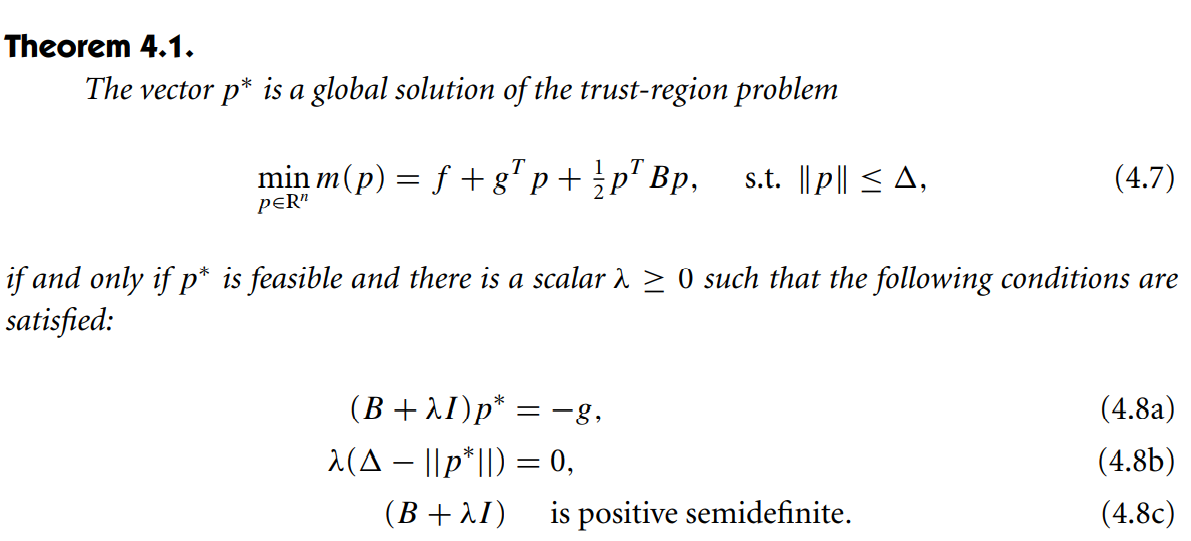

Remarks:

- (4.8b) is called the complementarity condition

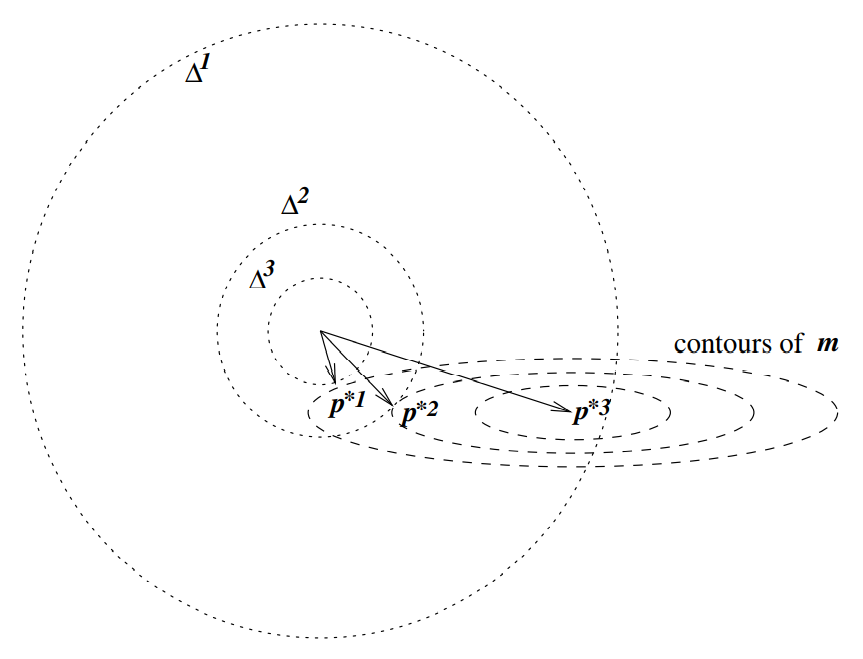

**HOW TO SOLVE THE SUBPROBLEMS?**


$$\min_{p}{m_k(p)}= f_k+g_k^Tp_k + \frac{1}{2}p^TB_kp, \quad \text{subject to }  \quad \|p\|_2\leq \Delta_k$$


#### 4.1 ALGORITHMS BASED ON THE CAUCHY POINT

**Four approximate methods** 

- Cauchy point 

- The dogleg method

- Two-dimensional subspace minimization 

- Steihaug’s algorithm (chapter 7)

#### 1. THE CAUCHY POINT (not really a method; use as a benchmark)

The **Cauchy point** is obtained when a steepest descent linesearch is applied to $m_k$ at $x_k$ and is restricted to $R_k$.

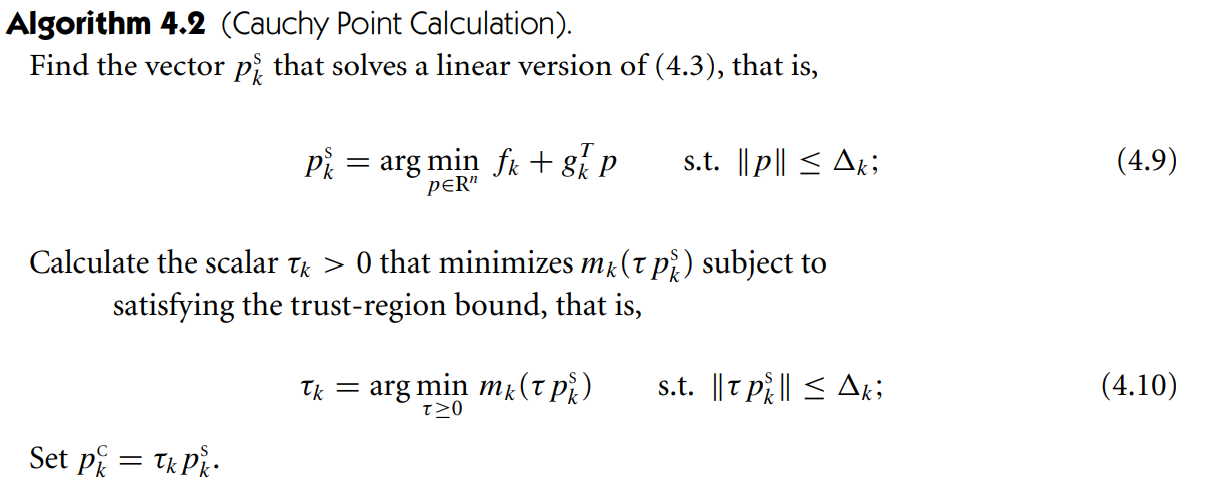

- 
$$p_k^S=-\frac{\Delta_k}{\|g_k\|}g_k$$


- The solution is $p_k^C= -\tau_k \frac{\Delta_k}{\|g_k\|}g_k$ (Cauchy point)

- 
$$\tau_k=\left\{ \begin{array}{lll} 1 & \text{if} & g_k^TB_kg_k\leq0\\ & \\ \min\left(\frac{\|g_k\|^3}{\Delta_kg_k^TB_Kg_k},1\right)&\text{if} &g_k^TB_kg_k > 0\end{array}\right.$$


- The Cauchy step $p^C_k$ is inexpensive to calculate

- A trust-region method will be globally convergent if its steps $p_k$ give a reduction in the model $m_k$ that is at least some fixed positive multiple of the decrease attained by the Cauchy step.

- Slow convergence

- Use as a reference direction

- More on this in chap 5

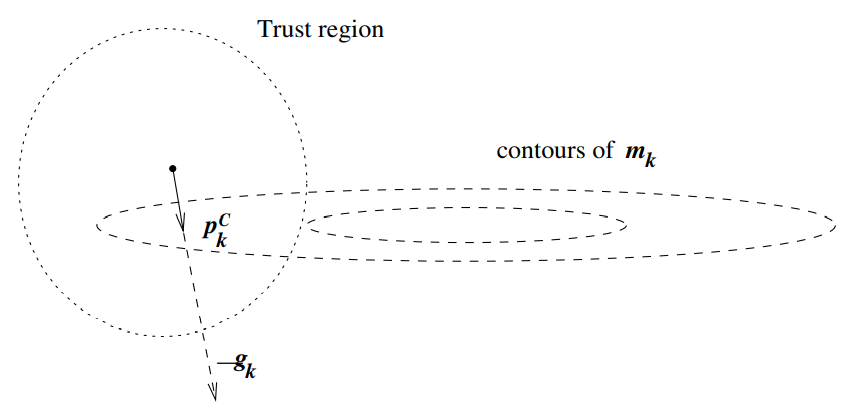

#### THE DOGLEG METHOD

We assum that $B>0$.

**Motivation:** 

Let 


$$p^*(∆) = {\text{arg\!\!}\min}_{p\in \mathbb{R}^n | \|p\|\le ∆} {m_k(p)}=p^B=-B^{-1}g, \text{ provided that } \|p^B\|\leq \Delta.$$


If $B_k> 0$ then $∆ \to p^*(∆)$ describes a curvilinear path from $p^*(0) = x_k$ to the exact minimizer of the unconstrained problem $\min_{p\in \mathbb{R}^n} m_k(p),$ that is, to the quasi-Newton point $p^B = - B^{-1}g$

We examine the effect of the trust-region radius $\Delta$ on the solution $p^\ast (\Delta)$ of the subproblem

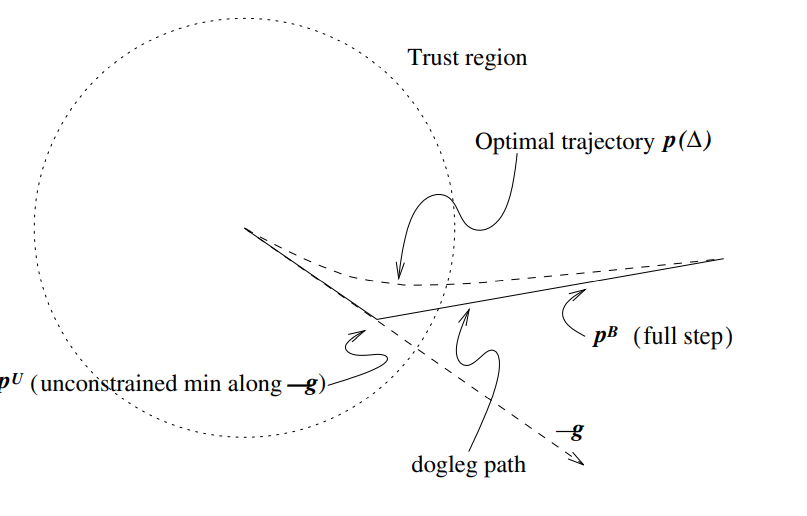

The dogleg method finds an approximate solution by replacing the curved trajectory for $p^\ast (\Delta)$ with a path consisting of two line segments $\tilde{p}(\tau)$. 

- The first line segment runs from the origin to the minimizer of $m$ along the steepest descent direction, which is (Cauchy point) $p^U = -\frac{g^Tg}{g^TBg}g$.

- The second line segment runs from $p^U$ to $p^B$. Here $p^B$ is a Newton direction of $m$.

The dogleg path is thus described by


$$\tilde{p}(\tau)=\left\{\begin{array}{lll} \tau p^U, &\text{if}, &\tau\in [0,1]\\ p^U + (\tau-1)(p^B-p^U) &\text{if} & \tau \in [1,2]\end{array}\right.$$


The dogleg method chooses $p$ to minimize the model $m$ along this path, subject to the trust-region bound. The following lemma shows that the minimum along the dogleg path can be found easily

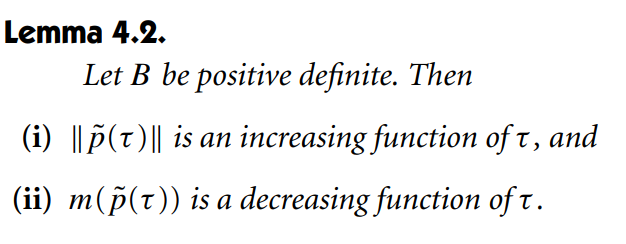

**Algorithm: Dogleg Point**. 

- compute $p^u_k$  

- if $p^u_k \ge  ∆_k$ stop with $p_{k} = \frac{\Delta_k}{\|p^U\|}p^U$  

- compute $p^B_k$

- if $p^B_k \le  ∆_k$ stop with $p_k =p^B_k$

- else begin 

-     find $\tau^* \text{  s.t.  } \|p^U+(\tau^*-1)(p^B-p^U)\|=\Delta_k$

-     stop with $p_k =p^U+(\tau^*-1)(p^B-p^U)$  

- end

### TWO-DIMENSIONAL SUBSPACE MINIMIZATION

We solve


$$\min_{p} {m(p)}=f+g^Tp+{1\over 2}p^TBp, \text{ s.t.  } \|p\|\leq \Delta. \quad p\in \text{span}\{g,B^{-1}g\}.$$


When $B$ has negative eigenvalues

- Find $\alpha$ such that $(B+\alpha I)$ is positive definite.

- If $\|(B+\alpha I)^{-1}g\|\leq \Delta_k, p=-(B+\alpha I)^{-1}g +v$, such that $v^T(B+\alpha I)^{-1}g\leq 0$. (To enssure that $\|p\|\geq \|(B+\alpha I)^{-1}g\|$.

- otherwise, $p\in \text{span}\{g, (B+\alpha I)^{-1}g\}$

#### 4.2 GLOBAL CONVERGENCE

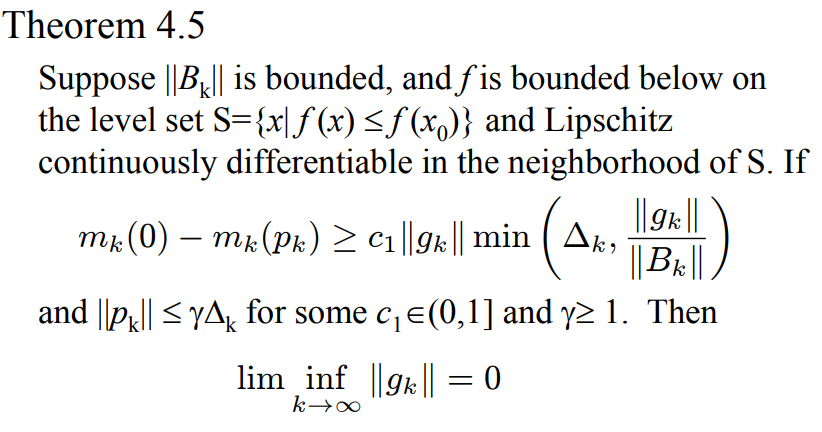

**Example 1:**


$$\min_{x\in \mathbb{R}^2}x_1^4+2x_1^3+24x_1^2+x_2^4+12x_2^2$$


clearvars;
f = @(x) x(1)^4+2*x(1)^3+24*x(1)^2+x(2)^4+12*x(2)^2;
ff = @(x,y) x.^4+2*x.^3+24*x.^2+y.^4+12*y.^2;
g = @(x) [4*x(1)^3+6*x(1)^2+48*x(1);4*x(2)^3+24*x(2)];
B = @(x) [12*x(1)^2+12*x(1)+48 0;0 12*x(2)^2+24];
m = @(xk,p) f(xk) + p'*g(xk) + 0.5*p'*B(xk)*p;
syms p1 p2 real

x0=[2;1];
m(x0,[p1;p2]);
pN= -(inv(B(x0))*g(x0))

pN =    -1.2667
   -0.7778



% first trust region
Delta = 1;
norm(pN)

ans = 1.4864

% (B+λI) p*=−g and λ(∆ −||p*||)=0
syms l;
Bl =(B(x0)+l*eye(2))

$$Bl = \left(\begin{array}{cc} l+120 & 0\\ 0 & l+36 \end{array}\right)$$

p = -Bl\g(x0);
eqn = norm(p)^2==1

$$eqn = \frac{784}{{\left|l+36\right|}^{2}}+\frac{23104}{{\left|l+120\right|}^{2}}=1$$

sol=solve(eqn,l,'Real',true);
lstart = max(real(vpa(sol)));
pstart = subs(p,l,lstart)

$$pstart = \left(\begin{array}{c} -0.9344920353219206835600190703085\\ -0.35598403885552810767775520199977 \end{array}\right)$$

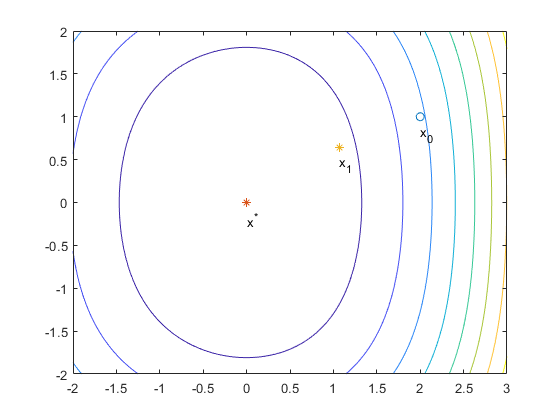

$$ans = 1.2450155746018846692925578453997$$

x1 = x0+pstart;
figure
x = linspace(-2,3);
y = linspace(-2,2);
[X,Y] = meshgrid(x,y);
Z = ff(X,Y);
contour(X,Y,Z)
hold on
plot(x0(1),x0(2),'o')
text(x0(1),x0(2)-0.2,'x_0')
plot(0,0,'*')
text(0,-0.2,'x^*')
plot(x1(1),x1(2),'*')
text(x1(1),x1(2)-0.2,'x_1')